# cargar_datos_xsens

Read a text file (.txt) generated by the xsens. Files format is:

// Start Time: 00/00/   0 - 01:10:50
// Sample rate: 120.0Hz
// Scenario: 10.8
// Firmware Version: 2.6.1
Counter	Temperature	Acc_X	Acc_Y	Acc_Z	Gyr_X	Gyr_Y	Gyr_Z	Mag_X	Mag_Y	Mag_Z	
43120	27.50	-9.786858	0.380128	0.469028	0.011950	-0.011256	0.001086	1.735953	0.008111	-0.222300	
43121	27.50	-9.772263	0.380142	0.461819	-0.005272	-0.008434	-0.010430	1.734197	0.007344	-0.222556	
43122	27.50	-9.769848	0.377685	0.466674	0.005068	-0.005865	-0.002433	1.737499	0.005634	-0.220332	
43123	27.50	-9.762546	0.384955	0.461846	0.003344	-0.005850	-0.003328	1.733951	0.008617	-0.222816	
43124	27.50	-9.772249	0.382594	0.456972	0.003375	0.006587	-0.002311	1.736374	0.008700	-0.221271	
43125	27.50	-9.767405	0.380130	0.461836	0.001632	-0.003165	-0.005056	1.734752	-0.000362	-0.225290	
43126	27.50	-9.767396	0.365654	0.457020	-0.002737	-0.001437	0.003549	1.734543	0.001509	-0.224798	
43127	27.50	-9.784419	0.389812	0.466598	-0.008807	-0.005866	0.003401	1.735723	0.002346	-0.223464	
43128	27.50	-9.772276	0.382527	0.466656	-0.005296	-0.000495	-0.002541	1.735324	0.007985	-0.222470
...

The Xsens are IMU (Inertial Measurement Unit) sensors that measure accelerations, rotation speeds and magnetic field strength on three perpendicular axes, or local reference system associated to the box containing it. The format of these data is the calibrated output format, which consists of 10 measurements in each sampling period.

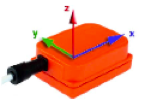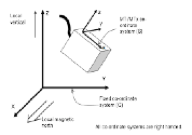

In addition, this IMU incorporates sensory integration algorithms (kalman filter) that provide drift-free sensor orientation with 1 degree accuracy:

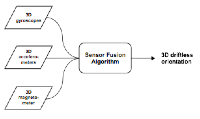

## Syntax

`[medicion]= cargar_datos_xsens(file,idname)`  

## Description

`[medicion]= cargar_datos_xsens(file,idname)` `file` is the name of the file, and `idname` an identifier of the data structure where the data will be stored. 

The data structure that the function creates has the form:

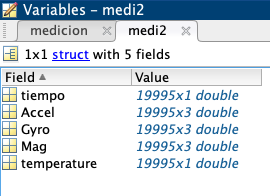 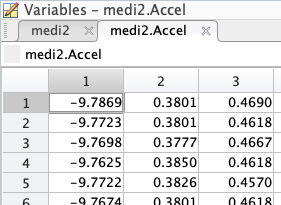

The work units are those corresponding to the international measurement system: m/s^2 for accelerations, rad/s for angular velocities, and u.a. (arbitrary units without real physical sense) for the measurement of the magnetic field. All toolbox functions expect to work with these units, and produce their results in units of the international system.

## Examples

% Lectura de un archivo:
[medi2] = cargar_datos_xsens('xsens_686aa.txt','sensorCOG')

medi2 = struct with fields:
         tiempo: [19995×1 double]
          Accel: [19995×3 double]
           Gyro: [19995×3 double]
            Mag: [19995×3 double]
    temperature: [19995×1 double]


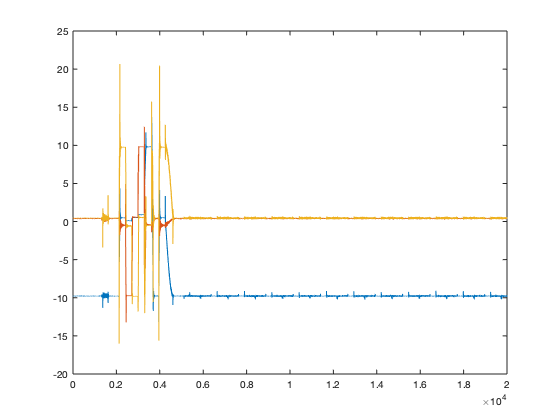


% Representa loa acelerometros:
plot(medi2.Accel)

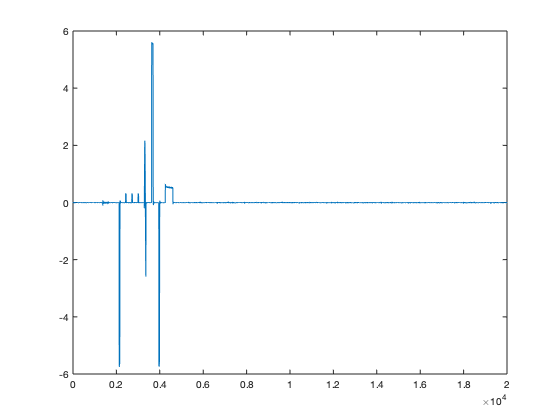

% El giroscopio en Y:
plot(medi2.Gyro(:,2))